# Quantization Aware Training for Transfer Learned Mobilenetv2

This example shows how to perform Quantization Aware Training on a transfer learned mobilenetv2 network.

Mobilenetv2 is an especially difficult network to perform post-training quantization on because of the depthwise-separable convolution layers that are sensitive to quantization. Quantization Aware Training helps by introducing quantization error while training giving the network the ability to recover loss additional training. 

The experiment requires the [Deep Learning Toolbox Model Quantization Library](matlab:matlab.addons.supportpackage.internal.explorer.showSupportPackages('DLQUANTIZATIONLIB', 'tripwire')) support package.  Click the links for more information on the [dlquantizer](matlab:doc("dlquantizer")) and [Deep Network Quantizer app](http://web%28fullfile%28docroot%2C%20%27deeplearning/ref/deepnetworkquantizer-app.html'))).

This experiment requires the Deep Learning Toolbox Model *for MobileNet-v2 Network* support package. Before you run the experiment, install these support packages by calling the [mobilenetv2](matlab:doc("mobilenetv2")) function and click the download links. For more information on other pretrained networks that you can download from the Add-On Explorer, see [Pretrained Deep Neural Networks](matlab:helpview('deeplearning','pretrained_networks')).

## Load Flower Dataset

Download the flower dataset [1] if it does not yet exist in the current folder. 

imageFolder = downloadFlowerDataset();
imds = imageDatastore(imageFolder, ...
        IncludeSubfolders=true, ...
        LabelSource="foldernames");


Preview the data by selecting a sample of possible labels and visualizing the images.

classes = string(categories(imds.Labels));
sampleClass = classes(1)

sampleClass = "daisy"

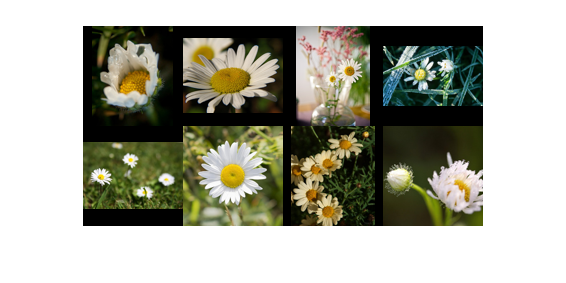

idxClass = find(imds.Labels == sampleClass);
idx = randsample(idxClass, 8);
imshow(imtile(imds.Files(idx),'GridSize',[2 4],'ThumbnailSize',[100 100]));

## Perform Transfer Learning on mobilenetv2

Mobilenetv2 is a convolutional neturall network 53 layers deep. The pretrained version of the network is trained on more than a million images from the ImageNet database. 

net = mobilenetv2;

Split the data into training and validation sets and create augmented image datastores that automatically resize the images to the input size of the network.

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.9);

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation);
validationActualLabels = imdsValidation.Labels;

Set a portion of the training dataset to use during the calibration step of quantization. This datastore should be representative of the data used for training but ideally separate from the one used to validate.

augimdsCalibration = subset(shuffle(augimdsTrain), 1:320);

Train mobilenetv2 on the flowers dataset to produce a baseline network that is still in `single `precision.

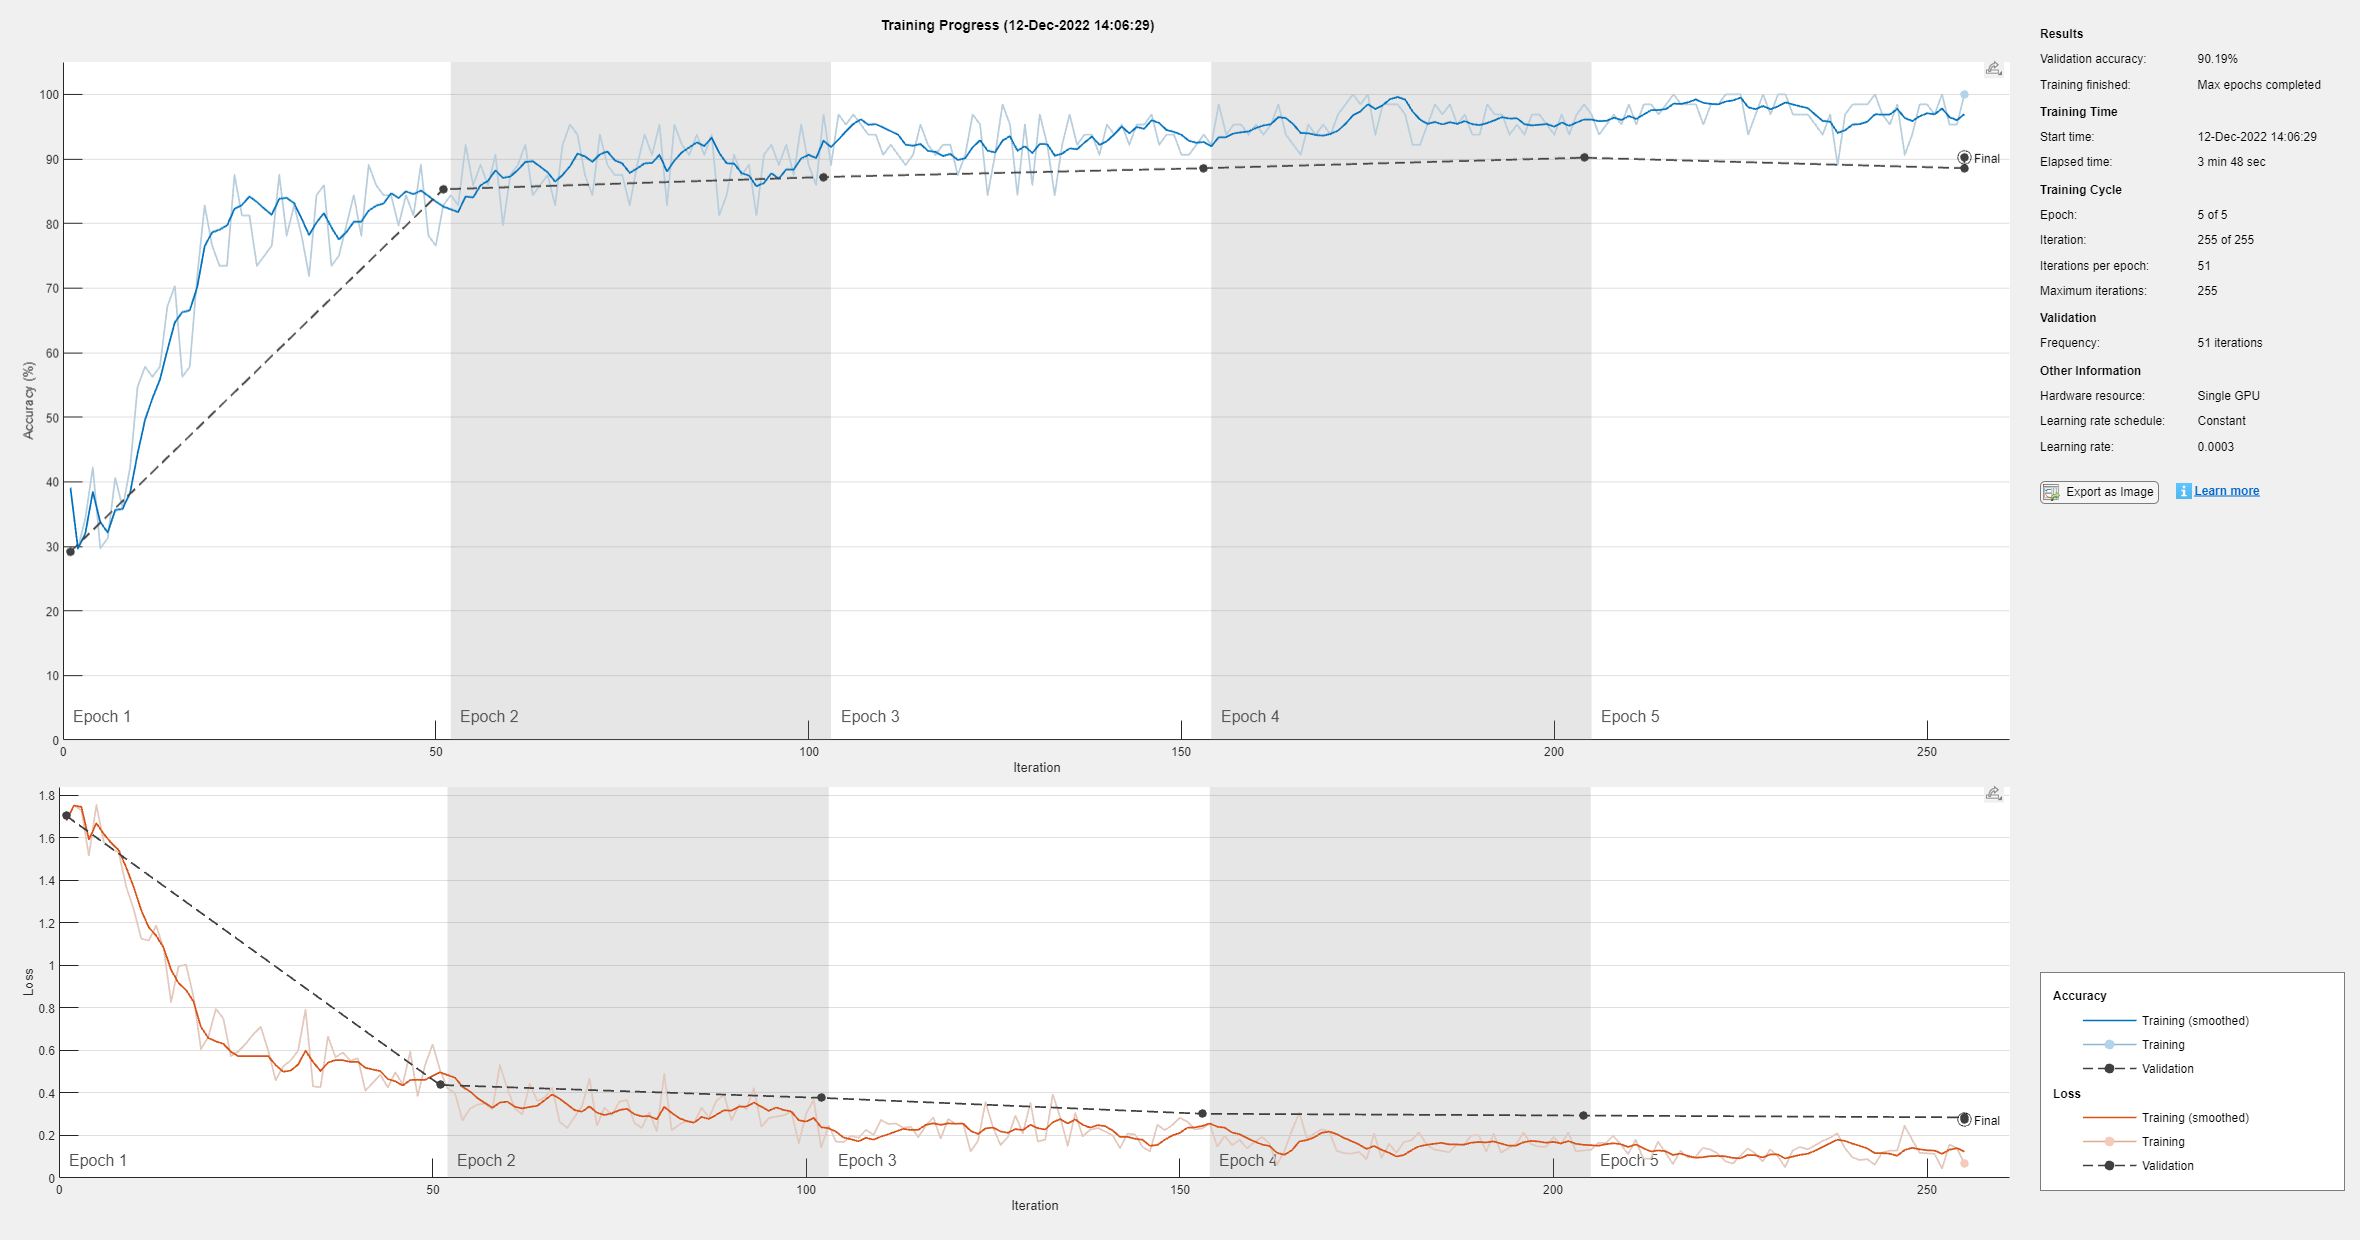

transferNet = createFlowerNetwork(net, augimdsTrain, augimdsValidation, classes);

## Evaluate Baseline Network Performance

Before continuing to quantization aware training, lets evaluate the performance of the original `single `precision network. Performance in this case is defined as the correct classification rate.

netCCR = evaluateModelAccuracy(transferNet, augimdsValidation, validationActualLabels) 

netCCR = 0.9019

Post-Training Quantization on the original network yields poor performance due to the range of learnable values in the depthwise separable convolution layer. An accuracy of roughly 20% is the equivalent to guessing one of the 5 possible labels for each image.

originalQuantizedNet = createQuantizedNetwork(transferNet, augimdsCalibration);
originalQuantizedCCR = evaluateModelAccuracy(originalQuantizedNet, augimdsValidation, validationActualLabels)

originalQuantizedCCR = 0.2997

## Replace original network layers with Quantization aware training layers

In this next step we replace the `Convolution2D` and `GroupedConvolution2D` layers along with their adjacent `BatchNormalization `layers with custom layers that are quantization aware. Quantization aware layers are custom layers that have modified `forward` and `predict` behavior that inject quantization error similar to that of post-training quantization. The quantization error comes from the newly insterted nodes "Boomerang Quantize w/STE". There nodes represent operaters that quantize, then unquantize a given value using best precision scaling to an int8 container. 

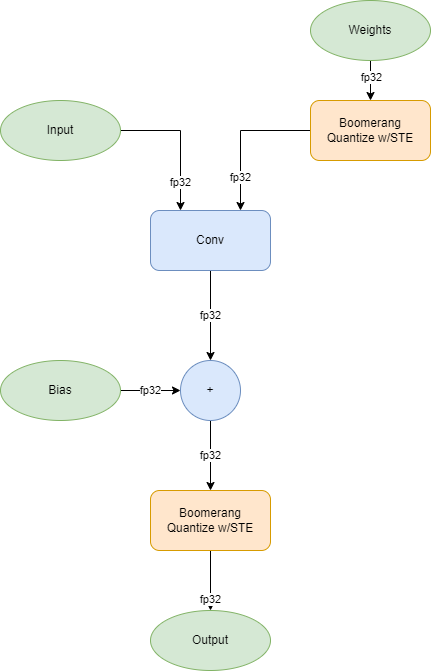

 
$$\begin{array}{l}
\mathrm{𝑥}̂=boomerangQuantize\left(\mathrm{𝑥}\right)\\
\;\;\;=\mathrm{unquantize}\left(\mathrm{quantize}\left(\mathrm{𝑥}\right)\right)\\
\;\;\;=\mathrm{rescale}\cdot \mathrm{saturate}\left(\mathrm{round}\left(\frac{\mathrm{𝑥}}{\mathrm{scale}}\right)\right)
\end{array}$$


The quantization step contains a round operation that is not differentiable. During the backwards pass, calculation of gradients for a round operation would result in 0 gradients. To avoid this problem, we use a "Straight-Through Estimator" to estimate the gradient with a simple identity function. See the diagram below [2] . 

 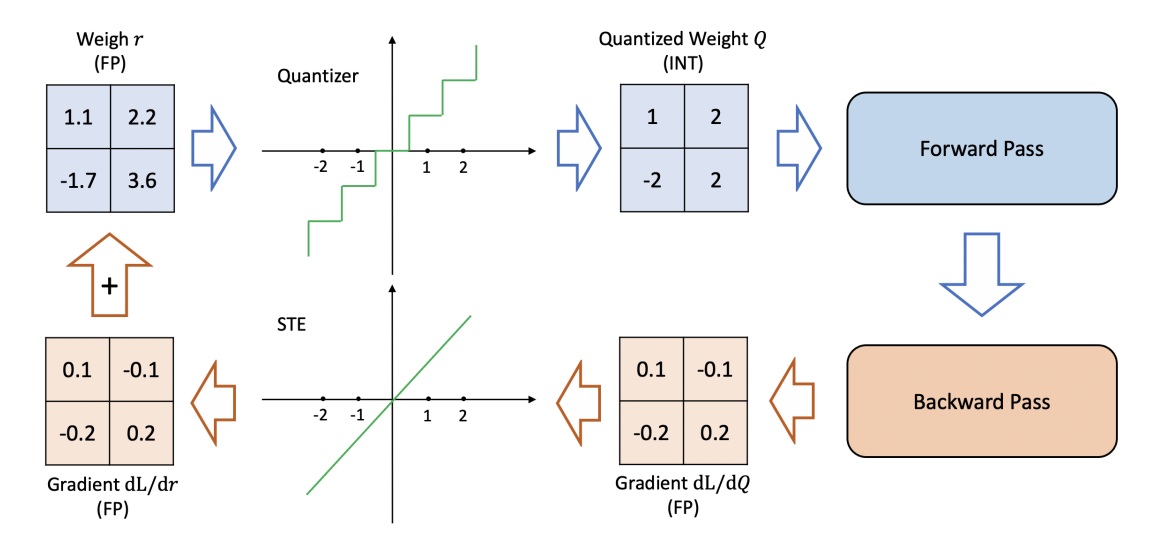

For Convolution2D layers, weights and bias are adjusted by folding in the BatchNormalization layer statistics. Next, the adjusted and quantized weights are used for the convolution operation. [3]

Since the BatchNormalization layer statistics have already been incorporated by the Convolution layer, we replace the BatchNormalization layer with an Identity layer. 

Should one apply Quantization Aware Training to a network that contains convolution layers without an adjactent bach normalization layer, one can use the `QuantizedConvolutionTrainingLayer `instead. For the mobilenetv2 example, only `QuantizedConvolutionBatchNormTrainingLayer `is used.

quantizationAwareLayerGraph = makeQuantizationAwareLayers(transferNet);

quantizationAwareLayerGraph.Layers

ans =   154×1 Layer array with layers:

     1   'input_1'                        Image Input                         224×224×3 images with 'zscore' normalization
     2   'Conv1'                          Quantized Fused Convolution Layer   Quantization Aware Conv-BN Layer Group for Training
     3   'bn_Conv1'                       Identity Training Layer             No operation to forward behavior
     4   'Conv1_relu'                     Clipped ReLU                        Clipped ReLU with ceiling 6
     5   'expanded_conv_depthwise'        Quantized Fused Convolution Layer   Quantization Aware Conv-BN Layer Group for Training
     6   'expanded_conv_depthwise_BN'     Identity Training Layer             No operation to forward behavior
     7   'expanded_conv_depthwise_relu'   Clipped ReLU                        Clipped ReLU with ceiling 6
     8   'expanded_conv_project'          Quantized Fused Convolut

## Do Quantization Aware Training

Using the LayerGraph with quantization aware training layers, do training as one normally would for transfer learning. The options in this case have been slightly modified to increase the number of `MaxEpochs` and the `ValidationFrequency` to every 2 epochs.

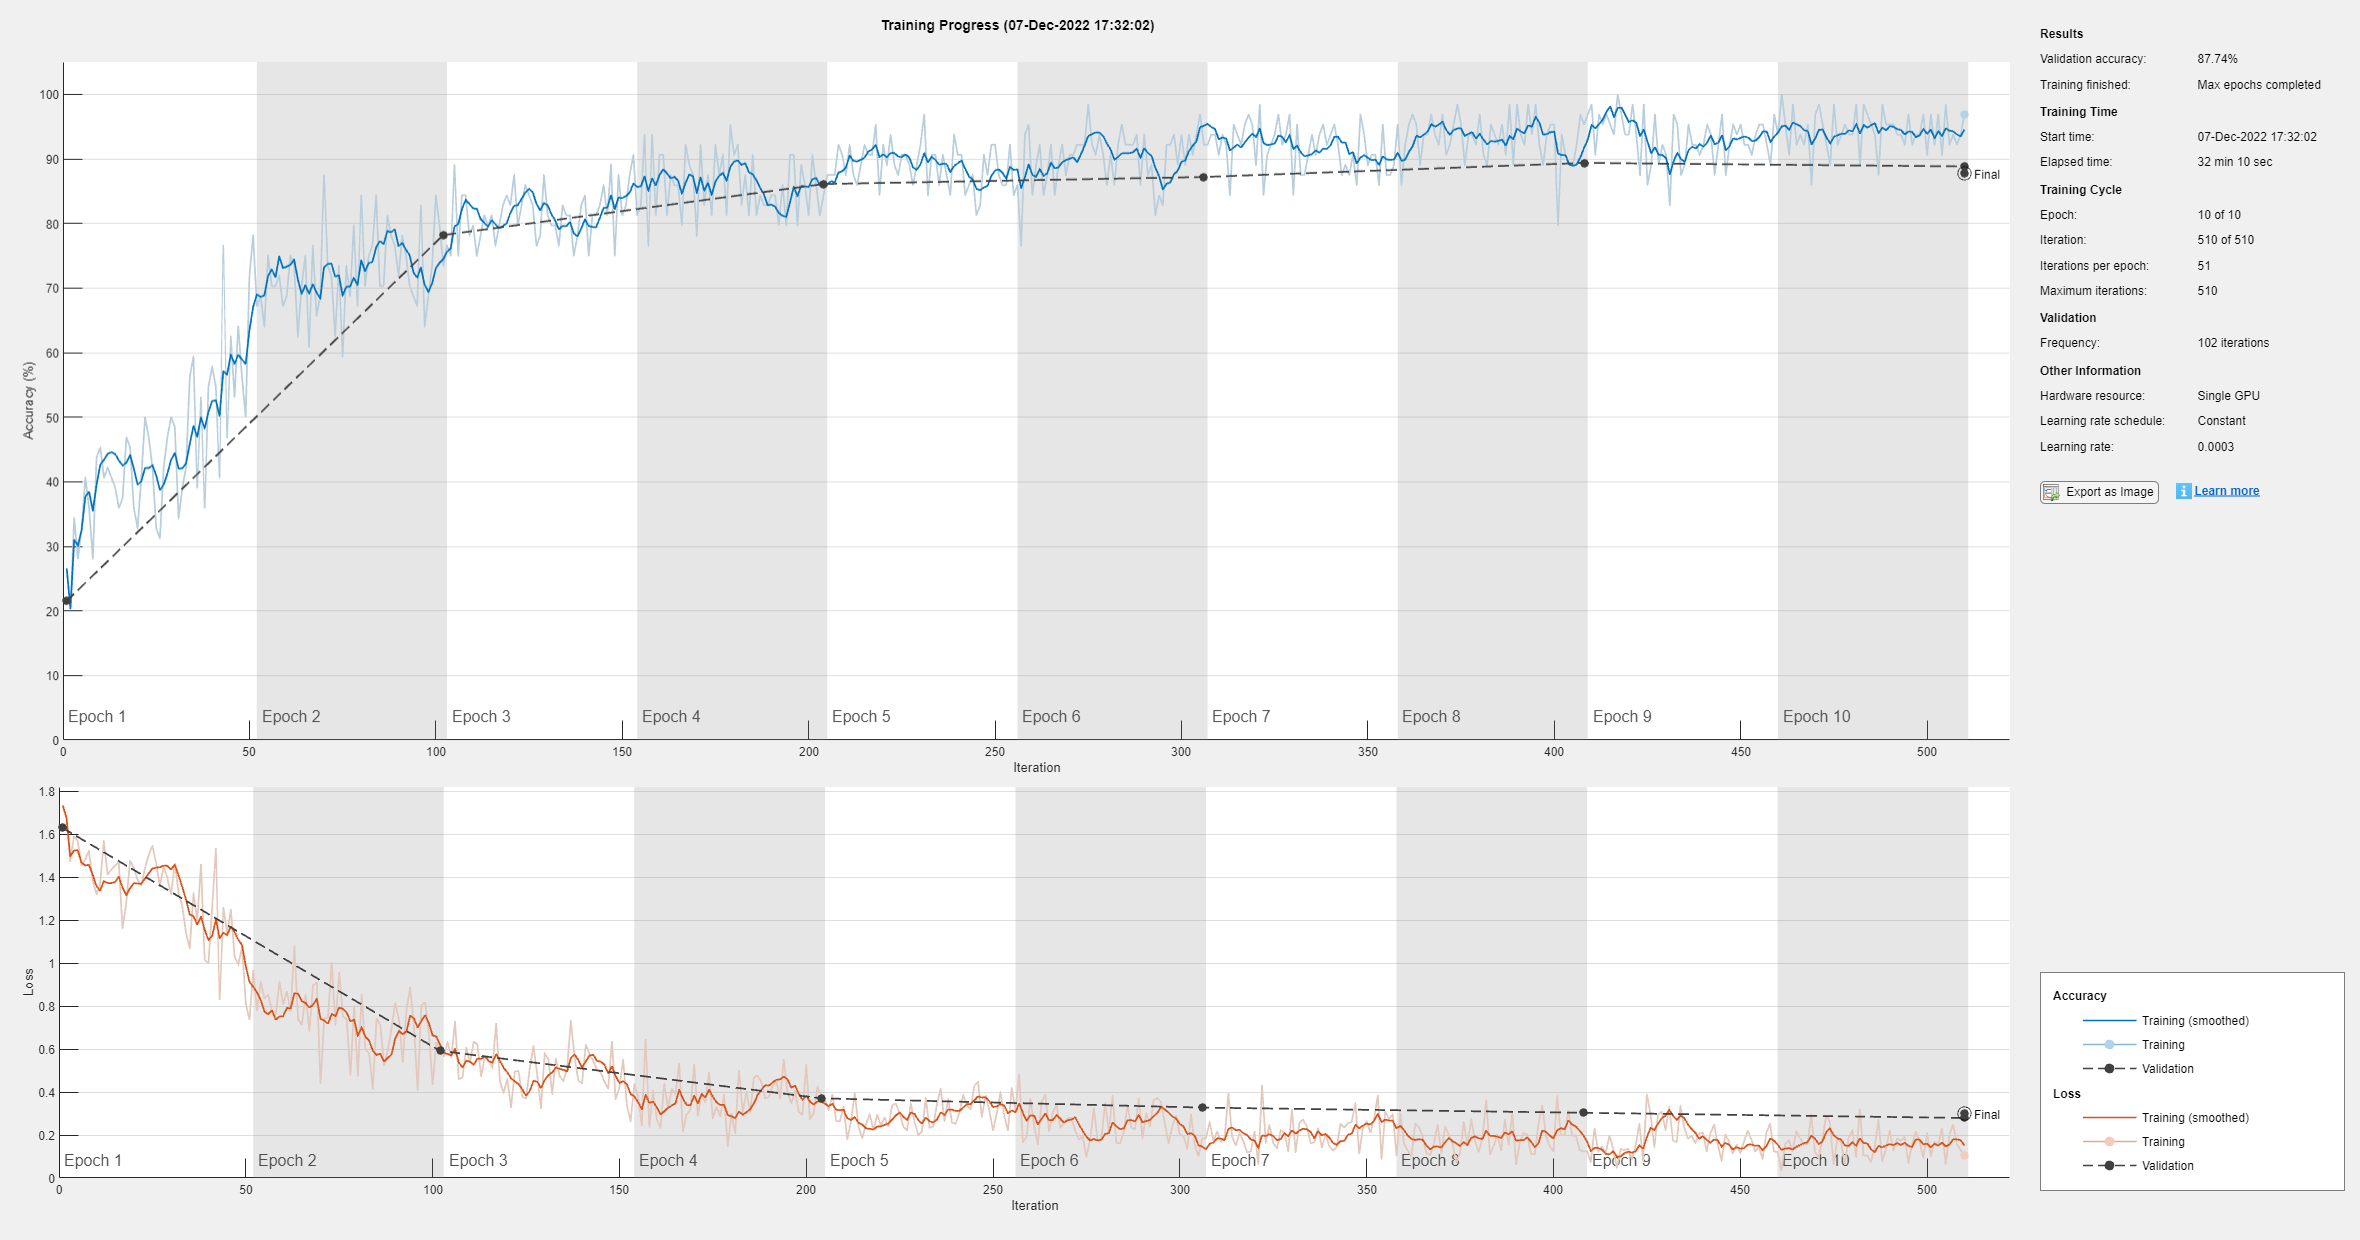

quantizationAwareTrainedNet =   DAGNetwork with properties:

         Layers: [154×1 nnet.cnn.layer.Layer]
    Connections: [163×2 table]
     InputNames: {'input_1'}
    OutputNames: {'new_classoutput'}


miniBatchSize = 64;
validationFrequencyEpochs = 2;
numObservations = augimdsTrain.NumObservations;
numIterationsPerEpoch = floor(numObservations/miniBatchSize);
validationFrequency = validationFrequencyEpochs * numIterationsPerEpoch;

options = trainingOptions("sgdm", ...
        MaxEpochs=10, ...
        MiniBatchSize=miniBatchSize, ...
        InitialLearnRate=3e-4, ...
        Shuffle="every-epoch", ...
        ValidationData=augimdsValidation, ...
        ValidationFrequency=validationFrequency, ...
        Plots="training-progress", ...
        Verbose=false);

quantizationAwareTrainedNet = trainNetwork(augimdsTrain, quantizationAwareLayerGraph, options)

## Create a Quantized Inference Network post-Quantization Aware Training

The network returned from the `trainNetwork` function still has the quantization aware training layers. The quantization aware training operators need to be replaced with operators that are specific to inference. Whereas the training graph operates on pseudo-quantized fp32 values, in the inference graph, convolution computation occurs in int8 using int8 inputs and weights. 

 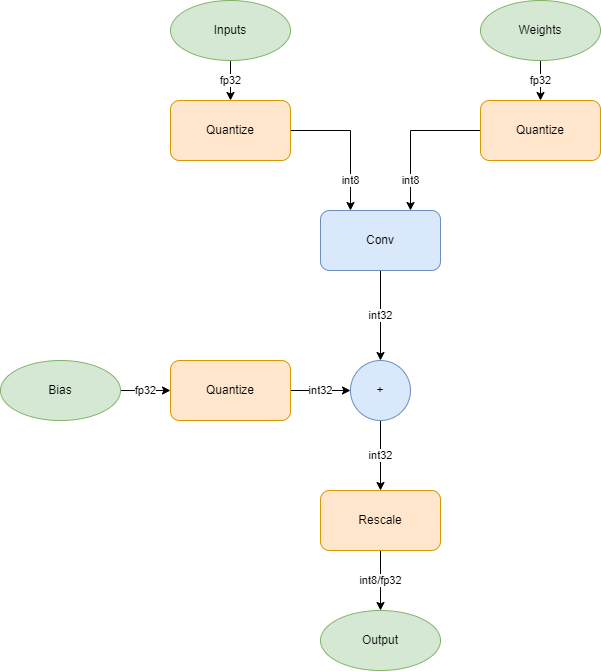

There are two steps to get to a fully quantized network. The first is to remove the quantization aware layers and replace with underlying learned convolution layers. 

unquantizedNetworkDetails = quantizationDetails(quantizationAwareTrainedNet)

unquantizedNetworkDetails = struct with fields:
            IsQuantized: 0
          TargetLibrary: ""
    QuantizedLayerNames: [0×0 string]
    QuantizedLearnables: [0×3 table]


preQuantizedNetwork = removeQuantizationAwareLayers(quantizationAwareTrainedNet);

Secondly, we can take the pre-quantized network through post-training quantization like we normally would to produce a fully quantized network. 

quantizationAwareQuantizedNet = createQuantizedNetwork(preQuantizedNetwork, augimdsCalibration);
quantizedNetworkDetails = quantizationDetails(quantizationAwareQuantizedNet)

quantizedNetworkDetails = struct with fields:
            IsQuantized: 1
          TargetLibrary: "cudnn"
    QuantizedLayerNames: [105×1 string]
    QuantizedLearnables: [60×3 table]


## Evaluate the post Quantization Aware Network

quantizedNetworkCCR = evaluateModelAccuracy(quantizationAwareQuantizedNet, augimdsValidation, validationActualLabels)

quantizedNetworkCCR = 0.8910

In summary, Quantization Aware Training can help recover accuracy loss from post-training quantization.  

table(netCCR, originalQuantizedCCR, quantizedNetworkCCR, ...
    'VariableNames', ["Original Network Accuracy", "Post-Training Quantization Accuracy", "Quantization Aware Training Accuracy"])

ans = 1×3 table
    Original Network Accuracy    Post-Training Quantization Accuracy    Quantization Aware Training Accuracy
    _________________________    ___________________________________    ____________________________________

             0.89646                           0.29428                                0.89101               


## References

- The TensorFlow Team. *Flowers* [http://download.tensorflow.org/example_images/flower_photos.tgz](http://download.tensorflow.org/example_images/flower_photos.tgz)

- Gholami, A., Kim, S., Dong, Z., Mahoney, M., & Keutzer, K. (2021). A Survey of Quantization Methods for Efficient Neural Network Inference. Retrieved from [https://arxiv.org/abs/2103.13630](https://arxiv.org/abs/2103.13630)

- Jacob, B., Kligys, S., Chen, B., Zhu, M., Tang, M., Howard, A., Adam, H., & Kalenichenko, D. (2017). Quantization and Training of Neural Networks for Efficient Integer-Arithmetic-Only Inference. Retrieved from [https://arxiv.org/abs/1712.05877](https://arxiv.org/abs/1712.05877)

## Helper Functions for Example using Mobilenetv2 and Flowers dataset

#### Evaluate Mode Accuracy

Compares the classify output of the network with the actual labels.

function ccr = evaluateModelAccuracy(net, valDS, labels)
    ypred = classify(net, valDS);
    ccr = mean(ypred == labels);
end

#### Create Quantized Network

Constructs a dlquantizer for `GPU` target and calibrates with a representative datastore.

function qNet = createQuantizedNetwork(net, calDS)
    dq = dlquantizer(net, "ExecutionEnvironment", 'GPU');
    dq.calibrate(calDS);
    qNet = dq.quantize();
end

#### Make Quantization Aware LayerGraph

Takes a DAGNetwork and replaced Convolution2D, GroupedConvolution2D and BatchNormalization layers with quantization aware versions.

function lg = makeQuantizationAwareLayers(net)
    lg = layerGraph(net);
    for idx = 1:numel(lg.Layers) - 1
        currentLayer = lg.Layers(idx);
        nextLayer = lg.Layers(idx + 1);

        if (isa(currentLayer, 'nnet.cnn.layer.Convolution2DLayer') ...
                || isa(currentLayer, 'nnet.cnn.layer.GroupedConvolution2DLayer'))
                
            if isa(nextLayer, 'nnet.cnn.layer.BatchNormalizationLayer')
                qLayer = QuantizedConvolutionBatchNormTrainingLayer(currentLayer, nextLayer);
                lg = replaceLayer(lg, currentLayer.Name, qLayer);

                qLayer = IdentityTrainingLayer(nextLayer);
                lg = replaceLayer(lg, nextLayer.Name, qLayer);
            else
                qLayer = QuantizedConvolutionTrainingLayer(currentLayer);
                lg = replaceLayer(lg, currentLayer.Name, qLayer);
            end
        end
    end
end

#### Remove Quantization Aware Layers from Network

Extract the original Layers from the Quantization Aware Layer and place back in the original layerGraph.

function net = removeQuantizationAwareLayers(qatNet)
    lg = layerGraph(qatNet);
    for idx = 1:numel(lg.Layers)
        currentLayer = lg.Layers(idx);
        if isa(currentLayer, 'QuantizedConvolutionTrainingLayer')
            
            cLayer = currentLayer.Network.Layers(1);
            lg = replaceLayer(lg, cLayer.Name, cLayer);

            bLayer = currentLayer.Network.Layers(2);
            lg = replaceLayer(lg, bLayer.Name, bLayer);
        end
    end
    net = assembleNetwork(lg);
end

#### Download Flower Dataset

Conditionally download and extract, if not yet in current working directory, the flowers data set [1]. 

function imageFolder = downloadFlowerDataset()
    url = "http://download.tensorflow.org/example_images/flower_photos.tgz";
    downloadFolder = pwd;
    filename = fullfile(downloadFolder,"flower_dataset.tgz");
    imageFolder = fullfile(downloadFolder,"flower_photos");
    if ~exist(imageFolder,"dir")
        disp("Downloading Flower Dataset (218 MB)...")
        websave(filename,url);
        untar(filename,downloadFolder)
    end

end

function transfer_net = createFlowerNetwork(net, augimdsTrain, augimdsValidation, classes)
    % Create a transfer-learned network using the given network as input
    % along with the data for training and validation

    % Define Network Architecture
    % Find and replace layers to perform transfer learning.
    lgraph = layerGraph(net);

    % Replace the Learnable Layer with a new one
    learnableLayer = lgraph.Layers(end-2);
    numClasses = numel(classes);
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
            Name="new_fc", ...
            WeightLearnRateFactor=10, ...
            BiasLearnRateFactor=10);
    lgraph = replaceLayer(lgraph, learnableLayer.Name, newLearnableLayer);

    % Replace the Classification Layer with a new one specific to the type
    % classes seen in the flowers dataset.
    classLayer = lgraph.Layers(end);
    newClassLayer = classificationLayer(Name="new_classoutput");
    lgraph = replaceLayer(lgraph, classLayer.Name, newClassLayer);

    % Specify Training Options
    miniBatchSize = 64;
    validationFrequencyEpochs = 1;
    numObservations = augimdsTrain.NumObservations;
    numIterationsPerEpoch = floor(numObservations/miniBatchSize);
    validationFrequency = validationFrequencyEpochs * numIterationsPerEpoch;
    
    options = trainingOptions("sgdm", ...
        MaxEpochs=5, ...
        MiniBatchSize=miniBatchSize, ...
        InitialLearnRate=3e-4, ...
        Shuffle="every-epoch", ...
        ValidationData=augimdsValidation, ...
        ValidationFrequency=validationFrequency, ...
        Plots="training-progress", ...
        Verbose=false);

    % Train the network
    transfer_net = trainNetwork(augimdsTrain, lgraph, options);
end
